
x = gpml_randn(0.8, 20, 1);                 % 20 training inputs
y = sin(3*x) + 0.1*gpml_randn(0.9, 20, 1);  % 20 noisy training targets
xs = linspace(-4, 4, 81)';                  % 61 test inputs


GP nach Rasmussen

%We need specify mean, covariance and likelihood functions
meanfunc = [];                % empty: don't use a mean function
covfunc = @covSEiso;          % Squared Exponental covariance function
likfunc = @likGauss;          % Gaussian likelihood
  
%initialize the hyperparameter struct
hyp = struct('mean', [], 'cov', [0 0], 'lik', -1);
  
hyp2 = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, x, y);

Function evaluation      0;  Value 1.645700e+01
Function evaluation      6;  Value 8.030936e+00
Function evaluation      8;  Value -1.652225e+00
Function evaluation     12;  Value -2.708810e+00
Function evaluation     14;  Value -2.751836e+00
Function evaluation     16;  Value -2.781880e+00
Function evaluation     19;  Value -2.782112e+00
Function evaluation     21;  Value -2.782128e+00
Function evaluation     23;  Value -2.782130e+00
Function evaluation     26;  Value -2.782130e+00
Function evaluation     28;  Value -2.782130e+00
Function evaluation     30;  Value -2.782130e+00
Function evaluation     31;  Value -2.782130e+00
Function evaluation     34;  Value -2.782130e+00
Function evaluation     37;  Value -2.782130e+00
Function evaluation     38;  Value -2.782130e+00


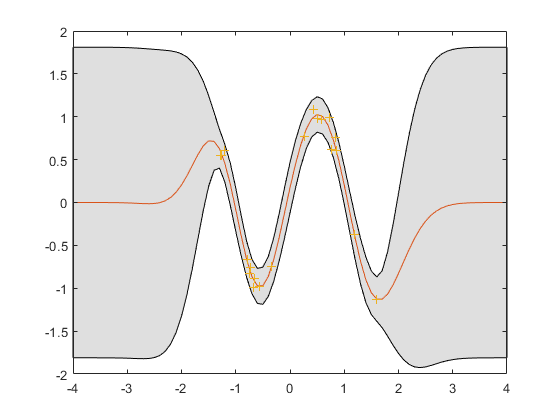


%predictions
  [mu s2] = gp(hyp2, @infGaussLik, meanfunc, covfunc, likfunc, x, y, xs);
    
  f = [mu+2*sqrt(s2); flipdim(mu-2*sqrt(s2),1)];
  fill([xs; flipdim(xs,1)], f, [7 7 7]/8)
  hold on; 
  plot(xs, mu); 
  plot(x, y, '+')
  hold off;

% GP nach eigenen Funktionen
theta = [1;1;1];

[theta, logLike] = scaledConjugateGradient(@Error,@DelLogLik,theta,x,y,10^-6 ,10^-4)

Delta = 0.6809

9.


w =     0.8068
   -0.1072
    0.8162


r =    -1.1351
    0.7799
   -1.4526


Emin = 22.5056

Delta = -4.1394

increase scale
9.


w =     0.8068
   -0.1072
    0.8162


r =    -1.1351
    0.7799
   -1.4526


Emin = 22.5056

Delta = -1.0006

increase scale
9.


w =     0.8068
   -0.1072
    0.8162


r =    -1.1351
    0.7799
   -1.4526


Emin = 22.5056

theta =     0.8068
   -0.1072
    0.8162


logLike = 22.5056

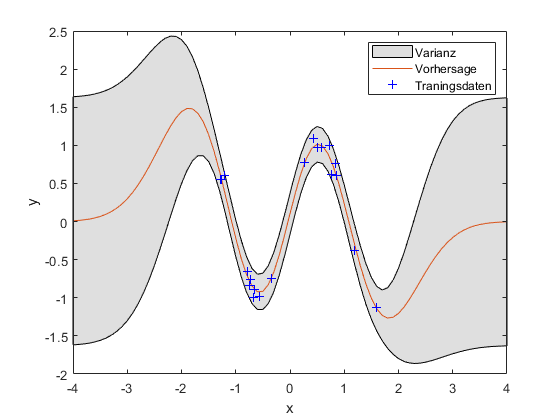

%theta = [0.9;0.092;0.53];

n = length(y);
K = CovMatrix(x,theta(1),theta(3));
K_y = (K + theta(2)^2 * eye(n))^-1;

yPredict = zeros(length(xs),1);
sig = zeros(length(xs),1);

for i = 1: length(xs)
    [yPredict(i),sig(i)] = GPpredict_V1(K_y,x,y,xs(i),theta(1),theta(2),theta(3));
end
    sig = sig + theta(2)^2;
    
  xs2 = [xs; flipdim(xs,1)];  
  f = [yPredict+2*sqrt(sig); flipdim(yPredict-2*sqrt(sig),1)];
  fill([xs; flipdim(xs,1)], f, [7 7 7]/8)
  hold on; 
  plot(xs, yPredict); 
  plot(x, y, 'b+' ...
      )
  hold off;
  legend('Varianz','Vorhersage','Traningsdaten')
  xlabel('x')
  ylabel('y')

Funktionen

function DLL = DelLogLik(w,x,y)
    n = length(y);
    delK = zeros (n,n,3);
    DLL = zeros(3,1);
    
    K = CovMatrix(x,w(1),w(3))+eye(n);
    
    %Del K berechnen
    delK(:,:,2) = 2 * w(2) * eye(n);
    
    for i = 1 : n
        for j = 1: n
        d =(x(i,:)-x(j,:)) * ((x(i,:)-x(j,:)).');
        
        delK(i,j,1) = 2* w(1)          * exp(-1/(2*w(3)^2)*d);
        delK(i,j,3) =  w(1)^2 * d/w(3)^3 * exp(-1/(2*w(3)^2)*d);
        end
    end
    %K_inv= chol(K+eye(n));
    K_inv= (K+eye(n))^-1;
    a = K_inv*y;
    DLL(1) = -0.5 * trace((a*a.' - K_inv)*delK(:,:,1));
    % Hier Optimierung, da nur diagonale Werte übernommen 
    DLL(2) = -0.5 * trace((a*a.' - K_inv)*delK(:,:,2)); 
    DLL(3) = -0.5 * trace((a*a.' - K_inv)*delK(:,:,3));
end

function E = Error(theta,x,y)
    if length(theta) ==3
        sigmaF = theta(1);
        l = theta(2);
        sigmaN = theta(3);
    else
        sigmaN = theta;
        sigmaF= 1;
        l =1;  
    end
    K = CovMatrix(x,sigmaF,l);
    E = - logLikelihood_V1(y,K,sigmaN);
end